# Genomic Variant Types vs. Fractional Solvent Accessible Surface Area

This script is intended to represent the data in a plot. I've attempted to scatter plot the variant values over the fractional SASA. This version of the script is generalized to accept any GnomAD data and SASA data from any structure.

E. Senning

G. Wulffraat

## User input - shift variable 

shift = 0;
prompt1 = {'Is the positioning of your SASA data shifted relative to your gnomAD data? (y/n)'};
dlgtitle1 = 'Input';
dims1 = [1 40];
definput1 = {'y' 'n'};
isShift = inputdlg(prompt1,dlgtitle1,dims1,definput1);
isShift = cell2mat(isShift);

if isShift == 'y'
    prompt = {'By how many AA positions is your SASA data shifted relative to your gnomAD data? (ex: rat is shifted 1 from human gnomAD data)'};
    dlgtitle = 'Input';
    dims = [1 40];
    definput = {'0'};
    shift = inputdlg(prompt,dlgtitle,dims,definput); % rat = human + 1 (ex: human LEU = 110, in rat LEU = 111)
    shift = str2num(shift{1})
else
end 

shift = 1

## Import SASA (pyMOL) and variant (GnomAD) data files

% read in and clean gnomad data 
ds = tabularTextDatastore('sampleGnomadCSV.csv'); % original, ensamble, with all daggers removed

varTable = readall(ds); % all gnomad data 

% read in and format SASA data
sasaPyMOL = readcell('samplePymolSASA.txt'); % imports sasa data, col 5 contains useful portion
pat = alphanumericBoundary("start") + wildcardPattern(1,inf) + alphanumericBoundary("end"); % splitting pattern
sasa_split = extract(sasaPyMOL(:,5),pat); % split into AA, position, SASA
sasa_len = size(sasa_split,1); % num of SASA-measured AAs
sasa = zeros(sasa_len,2); % empty double

VEP = table2array(varTable(:,13)); % VEP column from gnomad csv
proCons = table2array(varTable(:,11)); % protein consequence column from gnomad csv
numAAs = 1000;% total number of AAs
AAnames = sasa_split(:,1); % 3-letter AA IDs
numVarTypes = zeros(numAAs,1); % empty 

for i = 1:sasa_len % formats SASA data for later functions
    y = str2double(cell2mat(sasa_split(i,2)));
    z = str2double(cell2mat(sasa_split(i,3)));
    sasa(i,1) = y;
    sasa(i,2) = z./100;
end

% isolate missense variants 
idx = contains(VEP,'missense_variant'); % finds all missense variants
proCons_miss = proCons(idx); % finds all protein consequences for missense variants 

% find the number of missense vars at each AA position 
for i = 1 : length(proCons_miss)
    varCell_fromShort = proCons_miss(i); % isolates the cell
    %head(varTable,4) % shows the column name and first 4 rows for varTable
    siteID = regexp(varCell_fromShort,'\d*','match'); % splits protein cons string by pattern 
    siteNum = str2num(cell2mat(siteID{1})); % gets the position # for the AA
    % cell2mat converts a cell array to an ordinary array
    numVarTypes(siteNum) = numVarTypes(siteNum) + 1; % adds 1 to array of 0s to indicate that position has a variant
end 

max = maxk(sasa(:,1),1) +shift; % starting AA position in SASA data 
min = mink(sasa(:,1),1) +shift; % ending AA position
numVarTypesIso = numVarTypes(min:max); % number of variants at each position, for the positions we care about


## Sort according to SASA

sasaOnly = sasa(:,2);
[sasaSorted, I]=sort(sasaOnly); % sasa values sorted by increasing value 

numVarTypesIsoSorted=numVarTypesIso(I); % number of variant types sorted by increasing SASA

AAnamesSorted = AAnames(I); % AA list, sorted according to SASA value from pdb
AApos = sasa(:,1);
AAposSorted = AApos(I);

## Plot

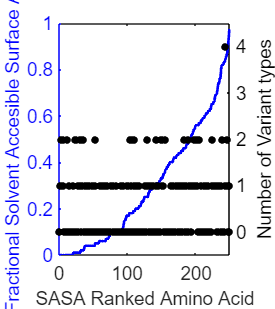

fig = figure('Position',[550 200 400,450]);
%title('TRPV1')
ax = gca; % current axes
ax.FontSize = 14;
colororder({'b','k'})
yyaxis left

plot(sasaSorted,'b-','LineWidth',2) % plots the line
hold all
ylabel('Fractional Solvent Accesible Surface Area','FontSize',14);
xlabel('SASA Ranked Amino Acid', 'FontSize',14);
yyaxis right

p = plot(numVarTypesIsoSorted,'ko', 'MarkerSize',5, 'MarkerFaceColor','k','LineWidth',0.7); % plots the dots

ylabel('Number of Variant types', 'FontSize',14);
ylim([-0.5 4.5])
xlim([0 250])
yticks([ 0.0 1.0 2.0 3.0 4.0]);
yticklabels({ '0', '1', '2', '3', '4'});
hold off

p.DataTipTemplate.DataTipRows(2).Label = "#var types:"; %labels Y as number of variants

row = dataTipTextRow("pos",AAposSorted); % labels AA position
p.DataTipTemplate.DataTipRows(end+1) = row;
row2 = dataTipTextRow("AA",AAnamesSorted); % labels which AA
p.DataTipTemplate.DataTipRows(end+1) = row2;
